## Doppler analysis

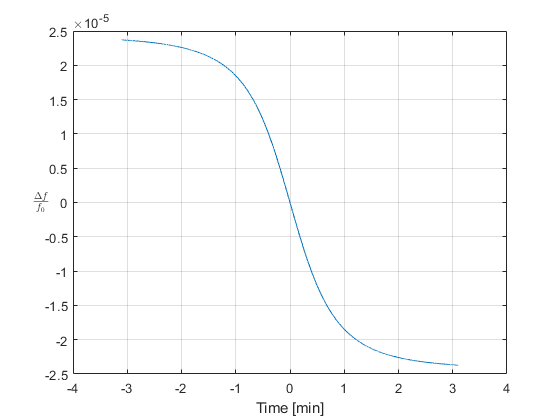

clc;
clear all;

% Data
c = 3e8;
r_e = 6366e3;
h = 400e3;
max_elevation = 90;
i = 90;
min_elevation = 10;
N = 10000;
fc = 450e6;


%Calculations

r = h+r_e;
w_e = 7.292124e-5;
w_s = sqrt(3.98601352e5/(r/1000)^3);
w_f = w_s -w_e *cosd(i);
v_s = w_s * r; 


cos_gamma_t0 = cosd(acosd((r_e/r)*cosd(max_elevation))-max_elevation);
cos_gamma_min =cosd(acosd((r_e/r)*cosd(min_elevation))-min_elevation);

visibility = (2/w_f)*acos(cos_gamma_min/cos_gamma_t0);

relative_tv = (visibility/2);
t = linspace (-relative_tv,relative_tv,N);
psi_delta = w_f*t;

A = cos_gamma_t0;
K = r_e * r;
B = r_e^2 +r^2;

relative_doppler = (-1/c) * ((K*sin(psi_delta)*A*w_f)./...
                    sqrt(B -2* K*cos(psi_delta)* A));
                


%relative_doppler_approx = - ((A*K*w_f^2)./(c*sqrt(B-2*A*K)))* t... 
%+ ((A*K*(B+A*K)*w_f^4)/(6*(c*sqrt(B-2*A*K)*(-B+2*A*K)))) .* t.^3;

%relative_doppler_approx = relative_doppler_approx *fc;

slope = - ((A*K*w_f^2)./(c*sqrt(B-2*A*K)))* fc;

W = w_f;
derivative_doppler = (A^2 * K*2 * W^2 * sin(psi_delta).^2 )...
                     ./(c*(B-2*A*K*cos(psi_delta)).^(3/2))...
                     - (K* W^2 * A * cos(psi_delta))...
                     ./(c*sqrt(B-2*A*K*cos(psi_delta)));
                 
derivative_doppler = derivative_doppler * (fc);

% Plotting
 

plot(t/60, relative_doppler);
xlabel('Time [min]');
ylabel('$\frac{\Delta f}{f_0}$','Interpreter','latex');
 hYLabel = get(gca,'YLabel');
 set(hYLabel,'rotation',0,'VerticalAlignment','middle')
grid on;

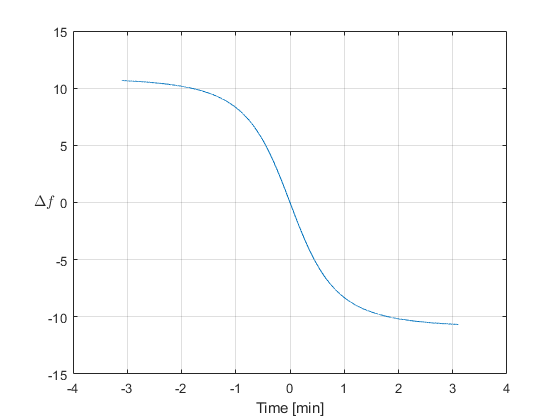

figure;
plot(t/60, (relative_doppler*fc)/1e3);
xlabel('Time [min]');
ylabel('$\Delta f$','Interpreter','latex');
 hYLabel = get(gca,'YLabel');
 set(hYLabel,'rotation',0,'VerticalAlignment','middle')
grid on;

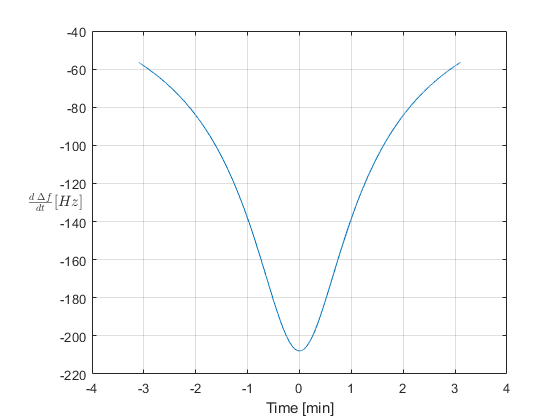


figure;
plot(t/60,derivative_doppler);
xlabel('Time [min]');
ylabel('$\frac{d \;\Delta f}{dt} [Hz]$','Interpreter','latex');
 hYLabel = get(gca,'YLabel');
 set(hYLabel,'rotation',0,'VerticalAlignment','middle')
 grid on;


fprintf(" ======= CONDITIONS =======\n\n");

 ======= CONDITIONS =======



fprintf("Carrier Frequency: %.2f MHz\n",fc/1e6);

Carrier Frequency: 450.00 MHz


fprintf("Orbit Height: %.2f km\n",h/1e3);

Orbit Height: 400.00 km


fprintf("Orbit inclination: %.2fº\n",i);

Orbit inclination: 90.00º


fprintf("Maximum elevation angle: %.2fº\n",max_elevation);

Maximum elevation angle: 90.00º


fprintf("Minimum elevation angle: %.2fº\n",min_elevation);

Minimum elevation angle: 10.00º


fprintf("Equivalent earth radius: %.2f km\n",r_e/1e3);

Equivalent earth radius: 6366.00 km


## Incremento de frecuencia en cada momento

### 1024 bytes por trama

N = 1024*8;    %Numero de bits del periodo
Rb = 1e6;      %Bitrate
fs = Rb/2;
fc = 450e6;

Ns = N/2;

tic
[t, relative_doppler] = doppler_frequency(fs,1);

Nt = size(t,2);

error_f = zeros(1,Nt-Ns);
for k=1:(Nt-Ns)
    error_f(1,k) = relative_doppler(1,k) - relative_doppler(1,k+Ns);  
end

error_f = abs(error_f);

toc

Elapsed time is 31.513600 seconds.


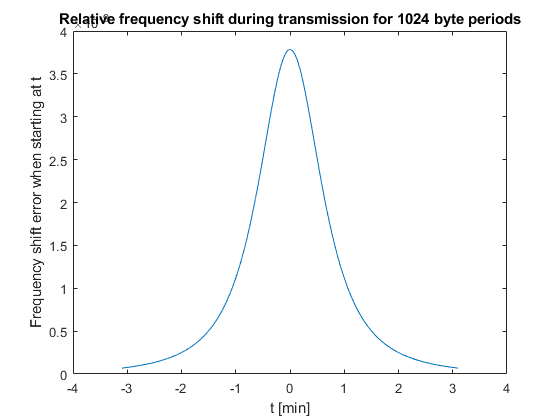


error_f = error_f(1:1000:(Nt-Ns));
t = t(1:1000:(Nt-Ns));
figure;

plot(t/60,error_f);
title("Relative frequency shift during transmission for 1024 byte periods");
xlabel("t [min]");
ylabel("Frequency shift error when starting at t");

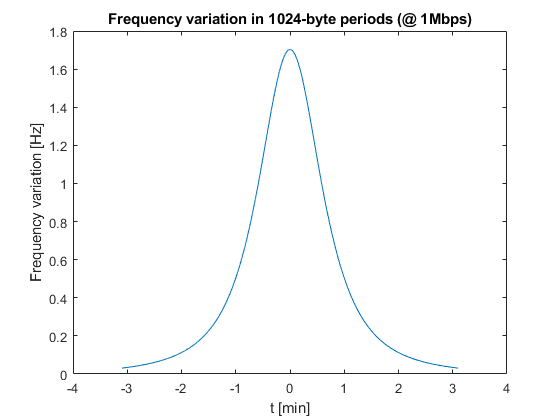

figure;
plot(t/60,error_f*fc);
title("Frequency variation in 1024-byte periods (@ 1Mbps)");
xlabel("t [min]");
ylabel("Frequency variation [Hz]");

### Para diferentes tramas

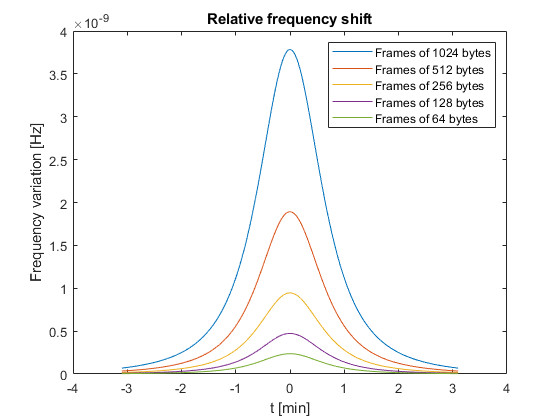

   %Numero de bits del periodo
Rb = 1e6;      %Bitrate
fs = Rb/2;
fc = 450e6;


[t, relative_doppler] = doppler_frequency(fs,1);
Nt = size(t,2);

% 1024 bytes
N = 1024*8; 
Ns = N/2;

error_f_1024 = zeros(1,Nt-Ns);
for k=1:(Nt-Ns)
    error_f_1024(1,k) = relative_doppler(1,k) - relative_doppler(1,k+Ns);  
end

error_f_1024 = abs(error_f_1024);


error_f_1024 = error_f_1024(1:1000:(Nt-Ns));
t_1024 = t(1:1000:(Nt-Ns));

% 512 bytes
N = 512*8; 
Ns = N/2;

error_f_512 = zeros(1,Nt-Ns);
for k=1:(Nt-Ns)
    error_f_512(1,k) = relative_doppler(1,k) - relative_doppler(1,k+Ns);  
end

error_f_512 = abs(error_f_512);


error_f_512 = error_f_512(1:1000:(Nt-Ns));
t_512 = t(1:1000:(Nt-Ns));

% 256 bytes
N = 256*8; 
Ns = N/2;

error_f_256 = zeros(1,Nt-Ns);
for k=1:(Nt-Ns)
    error_f_256(1,k) = relative_doppler(1,k) - relative_doppler(1,k+Ns);  
end

error_f_256 = abs(error_f_256);


error_f_256 = error_f_256(1:1000:(Nt-Ns));
t_256 = t(1:1000:(Nt-Ns));

% 128 bytes
N = 128*8; 
Ns = N/2;

error_f_128 = zeros(1,Nt-Ns);
for k=1:(Nt-Ns)
    error_f_128(1,k) = relative_doppler(1,k) - relative_doppler(1,k+Ns);  
end

error_f_128 = abs(error_f_128);


error_f_128 = error_f_128(1:1000:(Nt-Ns));
t_128 = t(1:1000:(Nt-Ns));

% 64 bytes
N = 64*8; 
Ns = N/2;

error_f_64 = zeros(1,Nt-Ns);
for k=1:(Nt-Ns)
    error_f_64(1,k) = relative_doppler(1,k) - relative_doppler(1,k+Ns);  
end

error_f_64 = abs(error_f_64);


error_f_64 = error_f_64(1:1000:(Nt-Ns));
t_64 = t(1:1000:(Nt-Ns));

close all;
figure;
plot(t_1024/60,error_f_1024);
hold on;
plot(t_512/60,error_f_512);
plot(t_256/60,error_f_256);
plot(t_128/60,error_f_128);
plot(t_64/60,error_f_64);
title("Relative frequency shift");
xlabel("t [min]");
ylabel("Frequency variation [Hz]");
legend("Frames of 1024 bytes",...
        "Frames of 512 bytes",...
        "Frames of 256 bytes",...
        "Frames of 128 bytes",...
        "Frames of 64 bytes");

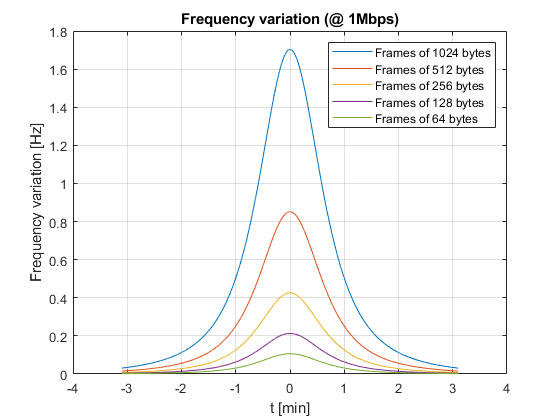


figure;
plot(t_1024/60,error_f_1024*fc);
hold on;
grid on;
plot(t_512/60,error_f_512*fc);
plot(t_256/60,error_f_256*fc);
plot(t_128/60,error_f_128*fc);
plot(t_64/60,error_f_64*fc);
title("Frequency variation (@ 1Mbps)");
xlabel("t [min]");
ylabel("Frequency variation [Hz]");
legend("Frames of 1024 bytes",...
        "Frames of 512 bytes",...
        "Frames of 256 bytes",...
        "Frames of 128 bytes",...
        "Frames of 64 bytes");